opts = delimitedTextImportOptions("NumVariables", 19);
opts.DataLines = [4, Inf];
opts.Delimiter = ",";
opts.VariableNames = ["scorer", "DLC_resnet50_WheelRunningProjectAug6shuffle1_60000", "DLC_resnet50_WheelRunningProjectAug6shuffle1_1", "DLC_resnet50_WheelRunningProjectAug6shuffle1_2", "DLC_resnet50_WheelRunningProjectAug6shuffle1_3", "DLC_resnet50_WheelRunningProjectAug6shuffle1_4", "DLC_resnet50_WheelRunningProjectAug6shuffle1_5", "DLC_resnet50_WheelRunningProjectAug6shuffle1_6", "DLC_resnet50_WheelRunningProjectAug6shuffle1_7", "DLC_resnet50_WheelRunningProjectAug6shuffle1_8", "DLC_resnet50_WheelRunningProjectAug6shuffle1_9", "DLC_resnet50_WheelRunningProjectAug6shuffle1_10", "DLC_resnet50_WheelRunningProjectAug6shuffle1_11", "DLC_resnet50_WheelRunningProjectAug6shuffle1_12", "DLC_resnet50_WheelRunningProjectAug6shuffle1_13", "DLC_resnet50_WheelRunningProjectAug6shuffle1_14", "DLC_resnet50_WheelRunningProjectAug6shuffle1_15", "DLC_resnet50_WheelRunningProjectAug6shuffle1_16", "DLC_resnet50_WheelRunningProjectAug6shuffle1_17"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

id = 1715;
authorNote = "60 DPI"; % for csv

fps = 100; 

filePath = "1715\1715_20260617_2026-06-17-191801-0000DLC_resnet50_Wheel Running ProjectAug6shuffle1_100000_filtered.csv";

pos = readtable(filePath, opts);

if authorNote == "150 DPI"
    pos = pos(1:(fps * 60 * 20), :);
end
if authorNote == "LDOPA"
    pos = pos((fps * 3000):(fps * 4200), :);
end

numFrames = size(pos, 1); % originally broken

clear opts

threshold_pawSpeed = 3; % pixels per frame
threshold_similarVector = 0.25; % percent (decimal)
threshold_wheelOn = 0.1; % speed of wheel in pixels per frame

frames = pos{:, 1};

fr_pos = pos{:, 5:7};

nose_pos = pos{:, 2:4};
fl_pos = pos{:, 8:10};
br_pos = pos{:, 11:13};
bl_pos = pos{:, 14:16};
tail_pos = pos{:, 17:19};

% fr_pos(fr_pos(:,3) < 0.9) = []; % delete

%{
plot(frames,fr_pos(:,1));
hold on
plot(frames,fr_pos(:,2));
hold off
legend('x', 'y')
%}

fr_vector = calculateVector(fr_pos);

nose_vector = calculateVector(nose_pos);
fl_vector = calculateVector(fl_pos);
br_vector = calculateVector(br_pos);
bl_vector = calculateVector(bl_pos);
tail_vector = calculateVector(tail_pos);

%{
plot(frames, fr_vector(:, 1));
hold on
plot(frames, fr_vector(:, 2));
plot(frames, fr_vector(:, 3));
plot(frames, fr_vector(:, 4));
hold off
legend('dx', 'dy', 'speed', 'angle(rad)')
%}

fr_gait = calculateGait(fr_vector)';

fl_gait = calculateGait(fl_vector)';
br_gait = calculateGait(br_vector)';
bl_gait = calculateGait(bl_vector)';

gait = [fr_gait, fl_gait, br_gait, bl_gait];
speed = [fr_vector(:, 3), fl_vector(:, 3), br_vector(:, 3), bl_vector(:, 3)];
angle = [fr_vector(:, 4), fl_vector(:, 4), br_vector(:, 4), bl_vector(:, 4)];

angle2 = changeRadiansInterval(angle); % change angle interval in radians from [-pi, pi] to [0, 2pi)

similarVectors = false(numFrames, 4);
for i = 1:4
    for j = i + 1:4
        avgSpeed = (speed(:, i) + speed(:, j))./ 2;
        diffSpeed = abs(speed(:, i) - speed(:, j))./ avgSpeed;

        diffAngle = abs(angle2(:, i) - angle2(:, j))./ (2 * pi);

        isSimilar = diffSpeed < threshold_similarVector & diffAngle < threshold_similarVector;

        similarVectors(:, i) = similarVectors(:, i) | isSimilar;
        similarVectors(:, j) = similarVectors(:, j) | isSimilar;    
    end
end

gaitOld = gait;
gait(similarVectors & gait == "swing") = "stand";
gait(speed < threshold_pawSpeed) = "stand";
[fr_filteredGait, fl_filteredGait, br_filteredGait, bl_filteredGait] = deal(gait(:,1), gait(:,2), gait(:,3), gait(:,4));

wheelSpeed = zeros(numFrames, 4);
wheelSpeed(similarVectors) = speed(similarVectors);
idx = angle2 > pi/2 & angle2 < 3*pi/2;
wheelSpeed(idx) = -wheelSpeed(idx);

## Plot Paws (Stand and Swing) and Wheel Over Frames

- filter wheel based on threshold_wheelOn

- graph constraints set by range

### Using Gait + Similar Vector Mapping

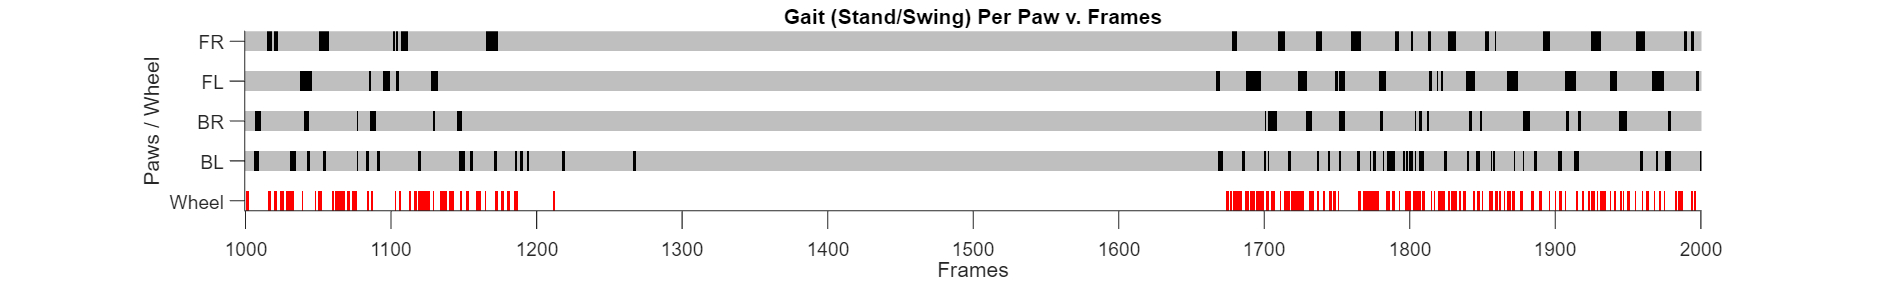

range = 1000:2000; % min and max frames

gaitNumeric = zeros(size(gait));
gaitNumeric(gait == "swing") = 1;

wheelOn = any(similarVectors, 2);
wheelOn(min(speed, [], 2) < threshold_wheelOn) = false; % bit of a stretch because the mouse can have a raised paw when the wheel is spinning

numFrames = numel(range);

img = ones(9, numFrames, 3);
rowMap = [1, 3, 5, 7];

% Paw rows: stand = gray, swing = black
for p = 1:4
    row = rowMap(p);

    img(row, :, :) = 0.75;

    swingFrames = gaitNumeric(range, p)' == 1;

    img(row, swingFrames, 1) = 0.00;
    img(row, swingFrames, 2) = 0.00;
    img(row, swingFrames, 3) = 0.00;
end

% Wheel row: off = white, on = red
wheelFrames = wheelOn(range)';

img(9, :, :) = 1.00;

img(9, wheelFrames, 1) = 1.00;

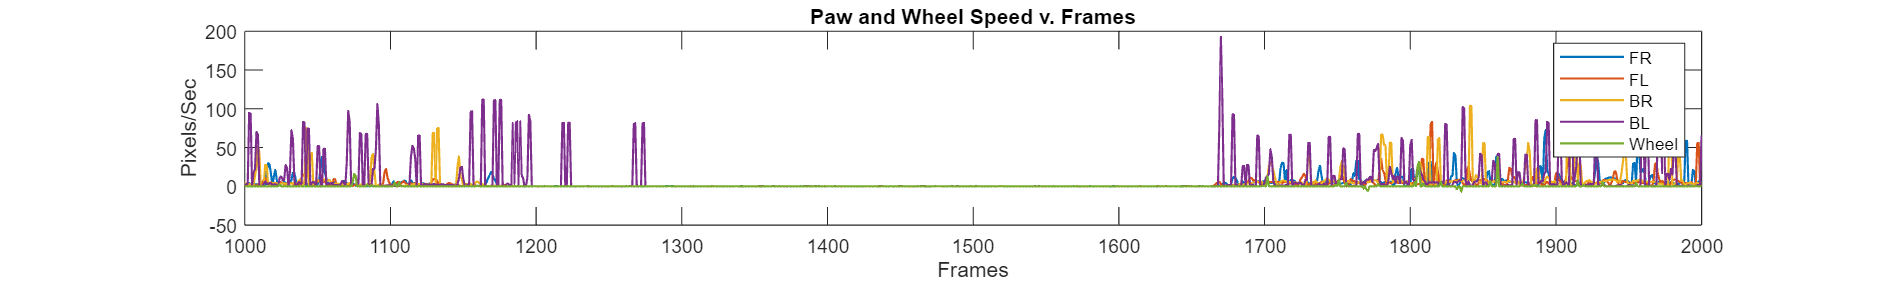

img(9, wheelFrames, 2) = 0.00;
img(9, wheelFrames, 3) = 0.00;

figure('Color', 'w', 'Position', [0 0 2000 300]);
image(range, 1:9, img);

title('Gait (Stand/Swing) Per Paw v. Frames');
xlabel('Frames');
ylabel('Paws / Wheel');

yticks([1 3 5 7 9]);
yticklabels({'FR', 'FL', 'BR', 'BL', 'Wheel'});

set(gca, 'TickDir', 'out', 'Box', 'off');
%{
for p = 1:4
    row = rowMap(p);

    img(row, :, :) = 0.75;

    swingFrames = similarVectors(range, p)' == 0;

    img(row, swingFrames, 1) = 0.00;
    img(row, swingFrames, 2) = 0.00;
    img(row, swingFrames, 3) = 0.00;
end

img(9, :, :) = 1.00;

img(9, wheelFrames, 1) = 1.00;
img(9, wheelFrames, 2) = 0.00;
img(9, wheelFrames, 3) = 0.00;

figure('Color', 'w', 'Position', [0 0 2000 300]);
image(range, 1:9, img);

title('Gait (Stand/Swing) Per Paw v. Frames');
xlabel('Frames');
ylabel('Paws / Wheel');

yticks([1 3 5 7 9]);
yticklabels({'FR', 'FL', 'BR', 'BL', 'Wheel'});


set(gca, 'TickDir', 'out', 'Box', 'off');
%}

figure('Color', 'w', 'Position', [0 0 2000 300]);

strideSpeed = -0.5133

plot(range, speed(range, :), LineWidth = 1);
hold on

fr_strideTotalLength = 6.5776e+05

fr_strideCount = 8855

fr_strideLength = 74.2808

fr_stepDistance = 104.0964

fr_stepLength = 68.7895

fr_stepWidth = 78.1285

plot(range, max(wheelSpeed(range, :), [], 2), LineWidth = 1)

fl_strideTotalLength = 6.3835e+05

fl_strideCount = 9282

fl_strideLength = 68.7725

fl_stepDistance = 90.9269

fl_stepLength = 75.6136

fl_stepWidth = 50.5004

br_strideTotalLength = 1.1363e+06

br_strideCount = 9711

br_strideLength = 117.0143

br_stepDistance = 83.0604

br_stepLength = 73.7381

br_stepWidth = 38.2326

title('Paw and Wheel Speed v. Frames');

bl_strideTotalLength = 1.3366e+06

bl_strideCount = 15221

bl_strideLength = 87.8102

bl_stepDistance = 112.5389

bl_stepLength = 90.5064

bl_stepWidth = 66.8850

xlabel('Frames');
ylabel('Pixels/Sec');

fr_standDutyFactor = 65.9809

fr_swingDutyFactor = 34.0191

fl_standDutyFactor = 64.0377

fl_swingDutyFactor = 35.9623

legend({'FR', 'FL', 'BR', 'BL', 'Wheel'})

br_standDutyFactor = 72.2700

br_swingDutyFactor = 27.7300

## Data Based on Sheppards et al Paper

- *angular velocity (angular velocity based on nose-tail axis)

- stride speed (speed of the mouse, calculated by the wheelspeed)

- limb duty factor (percentage of total time spent in swing/stand)

- temporal symmetry

- step length (distance the opposite side's paw travels past the other per swing)

- step width (distance between paws per swing)

- stride length (distance travelled per swing)

strideSpeed = mean(wheelSpeed, 'all')

bl_standDutyFactor = 64.3587

bl_swingDutyFactor = 35.6413


[fr_strideTotalLength, fr_strideCount, fr_strideLength, fr_stepDistance, fr_stepLength, fr_stepWidth] = calculateStrideLength(fr_filteredGait, fr_pos, fl_pos)

front_temporalSymmetry = -0.0149

[fl_strideTotalLength, fl_strideCount, fl_strideLength, fl_stepDistance, fl_stepLength, fl_stepWidth] = calculateStrideLength(fl_filteredGait, fl_pos, fr_pos)

back_temporalSymmetry = -0.0579

[br_strideTotalLength, br_strideCount, br_strideLength, br_stepDistance, br_stepLength, br_stepWidth] = calculateStrideLength(br_filteredGait, br_pos, bl_pos)
[bl_strideTotalLength, bl_strideCount, bl_strideLength, bl_stepDistance, bl_stepLength, bl_stepWidth] = calculateStrideLength(bl_filteredGait, bl_pos, br_pos)

[fr_standDutyFactor, fr_swingDutyFactor] = calculateDutyFactor(fr_gait)
[fl_standDutyFactor, fl_swingDutyFactor] = calculateDutyFactor(fl_gait)
[br_standDutyFactor, br_swingDutyFactor] = calculateDutyFactor(br_gait)
[bl_standDutyFactor, bl_swingDutyFactor] = calculateDutyFactor(bl_gait)

front_temporalSymmetry = calculateTemporalSymmetry(fl_standDutyFactor, fr_standDutyFactor) % stand only
back_temporalSymmetry = calculateTemporalSymmetry(bl_standDutyFactor, br_standDutyFactor)

angularVelocity = 1.0342e-07


front_dutyFactor = (fr_standDutyFactor + fl_standDutyFactor) / 2; % percentage time where paw on the ground

br_noseLateralDisplacement = 5.2660

br_noseLateralDisplacementPhaseOffset = 0.5201

back_dutyFactor = (fl_standDutyFactor + fl_standDutyFactor) / 2;

br_tailLateralDisplacement = 37.3267

br_tailLateralDisplacementPhaseOffset = 0.5274


dx_noseTail = nose_pos(:, 1) - tail_pos(:, 1);
dy_noseTail = nose_pos(:,2) - tail_pos(:,2);

noseTail_angle = atan2(dy_noseTail, dx_noseTail);
gradient(noseTail_angle);
angularVelocity = mean(gradient(noseTail_angle), 'all') % radians per frame

[br_noseLateralDisplacement, br_noseLateralDisplacementPhaseOffset] = calculateLateralDisplacement(br_gait, nose_pos) % lateral displacement and phase offset relative to stride cycles of back right paw (pixels)
[br_tailLateralDisplacement, br_tailLateralDisplacementPhaseOffset] = calculateLateralDisplacement(br_gait, tail_pos)
numFrames = size(pos, 1);
fr_strideCountPerFrame = fr_strideCount / numFrames;
fl_strideCountPerFrame = fl_strideCount / numFrames;
br_strideCountPerFrame = br_strideCount / numFrames;
bl_strideCountPerFrame = bl_strideCount / numFrames;

T = table(filePath, id, authorNote, ...
    strideSpeed, ...
    fr_strideLength, fr_stepLength, fr_stepWidth, ...
    fl_strideLength, fl_stepLength, fl_stepWidth, ...
    br_strideLength, br_stepLength, br_stepWidth, ...
    bl_strideLength, bl_stepLength, bl_stepWidth, ...
    front_temporalSymmetry, back_temporalSymmetry, ...
    front_dutyFactor, back_dutyFactor, ...
    angularVelocity, ...
    br_noseLateralDisplacement, br_noseLateralDisplacementPhaseOffset, ...
    br_tailLateralDisplacement, br_tailLateralDisplacementPhaseOffset, ...
    fr_strideCountPerFrame, fl_strideCountPerFrame, br_strideCountPerFrame, bl_strideCountPerFrame, ...
    'VariableNames', {'File Path', 'ID', 'Author''s Note', ...
    'Stride Speed', ...
    'Stride Length (FR)', 'Step Length (FR)', 'Step Width (FR)', ...

T = 1×29 table
                                                                                            File Path                                                                                              ID     Author's Note    Stride Speed    Stride Length (FR)    Step Length (FR)    Step Width (FR)    Stride Length (FL)    Step Length (FL)    Step Width (FL)    Stride Length (BR)    Step Length (BR)    Step Width (BR)    Stride Length (BL)    Step Length (BL)    Step Width (BL)    Temporal Symmetry (F)    Temporal Symmetry (B)    Duty Factor (F)    Duty Factor (B)    Angular Velocity    Nose Lateral Displacement (BR)

    'Stride Length (FL)', 'Step Length (FL)', 'Step Width (FL)', ...
    'Stride Length (BR)', 'Step Length (BR)', 'Step Width (BR)', ...
    'Stride Length (BL)', 'Step Length (BL)', 'Step Width (BL)', ...
    'Temporal Symmetry (F)', 'Temporal Symmetry (B)', ...
    'Duty Factor (F)', 'Duty Factor (B)', ...
    'Angular Velocity', ...
    'Nose Lateral Displacement (BR)', 'Nose Lateral Displacement Phase Offset (BR)', ...
    'Tail Lateral Displacement (BR)', 'Tail Lateral Displacement Phase Offset (BR)', ...
    'Stride Count Per Frame (FR)', 'Stride Count Per Frame (FL)', 'Stride Count Per Frame (BR)', 'Stride Count Per Frame (BL)'})
% writetable(T, 'Andrew Wheel Running Gait Analysis.csv')

% writetable(T, 'Andrew Wheel Running Gait Analysis.csv', 'WriteMode', 'append', 'WriteVariableNames', false);

%{
dataPath = 'Andrew Wheel Running Gait Analysis.csv';

oldT = readtable(dataPath, 'VariableNamingRule', 'preserve');

strideCountVars = {
    'Stride Count Per Frame (FR)', ...
    'Stride Count Per Frame (FL)', ...
    'Stride Count Per Frame (BR)', ...
    'Stride Count Per Frame (BL)'
};

rowToFill = find(string(oldT.('File Path')) == string(filePath), 1);
oldT{rowToFill, strideCountVars} = [
    fr_strideCountPerFrame, ...
    fl_strideCountPerFrame, ...
    br_strideCountPerFrame, ...
    bl_strideCountPerFrame
];

writetable(oldT, dataPath);
%}

function vector = calculateVector(pos)
    pos_x = pos(:, 1);
    pos_y = pos(:, 2);

    dx = gradient(pos_x);
    dy = gradient(pos_y);

    speed = sqrt(dx.^2 + dy.^2); % pixels per frame
    angle = atan2(dy, dx);

    vector = [dx, dy, speed, angle];
end

function gait = calculateGait(vector) % dir only, no mag; single column stand/swing
    angle = vector(:, 4);
    gait = strings(size(angle))';

    gait(isnan(angle)) = NaN;
    gait(angle <= pi / 2 & angle >= -pi / 2) = "swing";
    gait(angle >= pi / 2 | angle <= -pi / 2) = "stand";
end

function outputAngle = changeRadiansInterval(inputAngle) % change angle interval in radians from [-pi, pi] to [0, 2pi)
    outputAngle = inputAngle;
    outputAngle(inputAngle < 0) = 2 * pi + inputAngle(inputAngle < 0);
end

function [strideTotalLength, strideCount, strideLength, stepDistance, stepLength, stepWidth] = calculateStrideLength(gait, pos, opposite_pos)
    strideTotalLength = 0;
    strideCount = 0;

    stepTotalLength = 0;
    stepTotalWidth = 0;

    pos_1 = [];
    pos_2 = [];
    pos_3 = []; % for step

    if gait(1) == "swing"
        pos_1 = pos(1, :);
    end    
    
    for i = 2:numel(gait) - 1
        if gait(i) == "swing" && gait(i - 1) == "stand"
            pos_1 = pos(i, :);
        end

        if gait(i) == "swing" && gait(i + 1) == "stand"
            pos_2 = pos(i, :);
            strideTotalLength = strideTotalLength + norm(pos_1(1:2) - pos_2(1:2));

            pos_3 = opposite_pos(i, :);
            stepTotalWidth = stepTotalWidth + abs(pos_1(1) - pos_3(1)); % y
            stepTotalLength = stepTotalLength + abs(pos_1(2) - pos_3(2)); % x

            pos_1 = [];
            pos_2 = [];
            pos_3 = [];
            strideCount = strideCount + 1;
        end
    end

    if ~isempty(pos_1)
        pos_2 = pos(end, :);
        strideTotalLength = strideTotalLength + norm(pos_1(1:2) - pos_2(1:2));

        pos_3 = opposite_pos(end, :);
        stepTotalWidth = stepTotalWidth + abs(pos_1(1) - pos_3(1)); % y
        stepTotalLength = stepTotalLength + abs(pos_1(2) - pos_3(2)); % x

        strideCount = strideCount + 1;
    end

    strideLength = strideTotalLength / strideCount;
    stepLength = stepTotalLength / strideCount;
    stepWidth = stepTotalWidth / strideCount;
    stepDistance = sqrt(stepWidth^2 + stepLength^2);
end

function [standDutyFactor, swingDutyFactor] = calculateDutyFactor(gait)
    numFramesStand = sum(gait == "stand", 'all');
    standDutyFactor = numFramesStand / numel(gait) * 100; % percent
    swingDutyFactor = 100 - standDutyFactor;
end

function temporalSymmetry = calculateTemporalSymmetry(leftDutyFactor, rightDutyFactor)
    temporalSymmetry = (leftDutyFactor - rightDutyFactor) / (leftDutyFactor + rightDutyFactor);
end

function [lateralDisplacement, lateralDisplacementPhaseOffset] = calculateLateralDisplacement(gait, pos)
    lateralDisplacement = 0;
    lateralDisplacementPhaseOffset = 0;

    startFrame = 0;
    endFrame = 0;

    strideCycle = false; % stride cycle is swing + stand 

    strideCount = 0;
    
    if gait(1) == "swing" % assuming swing + stand as stride cycle, inverse for stand + swing
        startFrame = 1;
        strideCycle = true;
    end   

    for i = 2:numel(gait) - 1
        if gait(i) == "swing" && gait(i - 1) == "stand" % assuming swing + stand as stride cycle, inverse for stand + swing
            if strideCycle
                endFrame = i - 1;

                strideFrame = pos(startFrame:endFrame, 2);

                [yMax, idy] = max(strideFrame);

                lateralDisplacementPhaseOffset = lateralDisplacementPhaseOffset + idy / numel(strideFrame);
                lateralDisplacement = lateralDisplacement + (yMax - min(strideFrame));

                startFrame = 0;
                endFrame = 0;

                strideCount = strideCount + 1;
                
                strideCycle = false;
            else
                startFrame = i;
                
                strideCycle = true;
            end
        end
    end

    lateralDisplacement = lateralDisplacement / strideCount;
    lateralDisplacementPhaseOffset = lateralDisplacementPhaseOffset / strideCount;
end